## Part 2 : Finite Difference Method Laplace Equation

Lx=1; Ly=1; %rectangle dimensions
Nx = 50; Ny=50; %number of intervals in x,y directions
nx=Nx+1; ny=Ny+1; %number of gridpoints in x,y directions
dx=Lx/Nx; dy=Ly/Ny; %grid length in x,y directions
x=(0:Nx)*dx; y=(0:Ny)*dy; %x,y values on the grid

## Constructin A matrix

Next, the A matrix is constructed. The k indices of the boundary points are defined in the vector boundary_index, the five diagonals are placed in the A matrix using the Matlab spdiags function, and the rows associated with the boundary points are replaced by the corresponding rows of the identity matrix using speye:

boundary_index=[1:nx, 1:nx:1+(ny-1)*nx, 1+(ny-1)*nx:nx*ny, nx:nx:nx*ny];
diagonals = [4*ones(nx*ny,1), -ones(nx*ny,4)];
A=spdiags(diagonals,[0 -1 1 -nx nx], nx*ny, nx*ny);
I=speye(nx*ny);
A(boundary_index,:)=I(boundary_index,:);

## Constructin U matrix

 Interior rows are zero :

u=zeros(nx,ny);

## **Boundary Conditions (M = 2, N = 2, O = 3)**

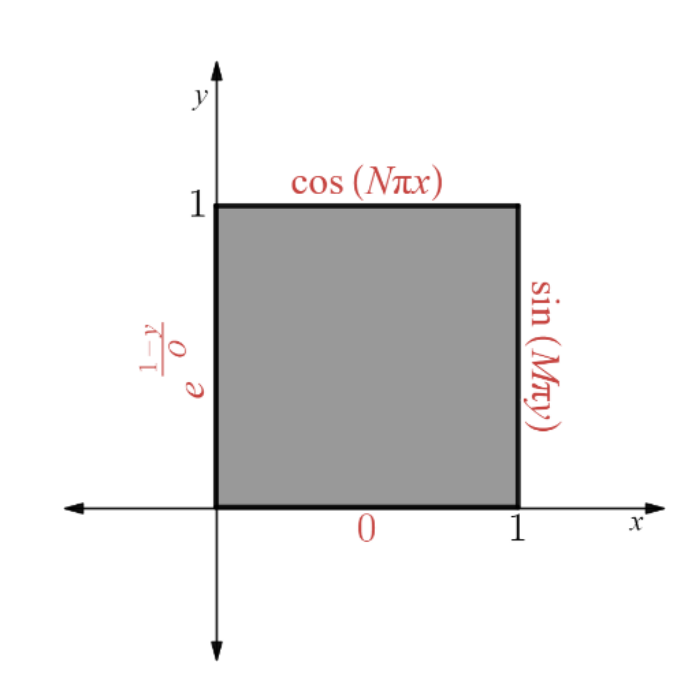

u(:,1)=0; %bottom
u(1,:)=1-y/3; %left
u(:,ny)=cos(2*pi*x); %top
u(nx,:)= sin(2*pi*y); %right

Make column vector using natural ordering [same as b=b(:)]

z=reshape(u,nx*ny,1);

## Solving the system of equations

Phi=A\z; %solution by Gaussian elimination
Phi=reshape(Phi,nx,ny); %back to (i,j) indexing

## Plotting the result

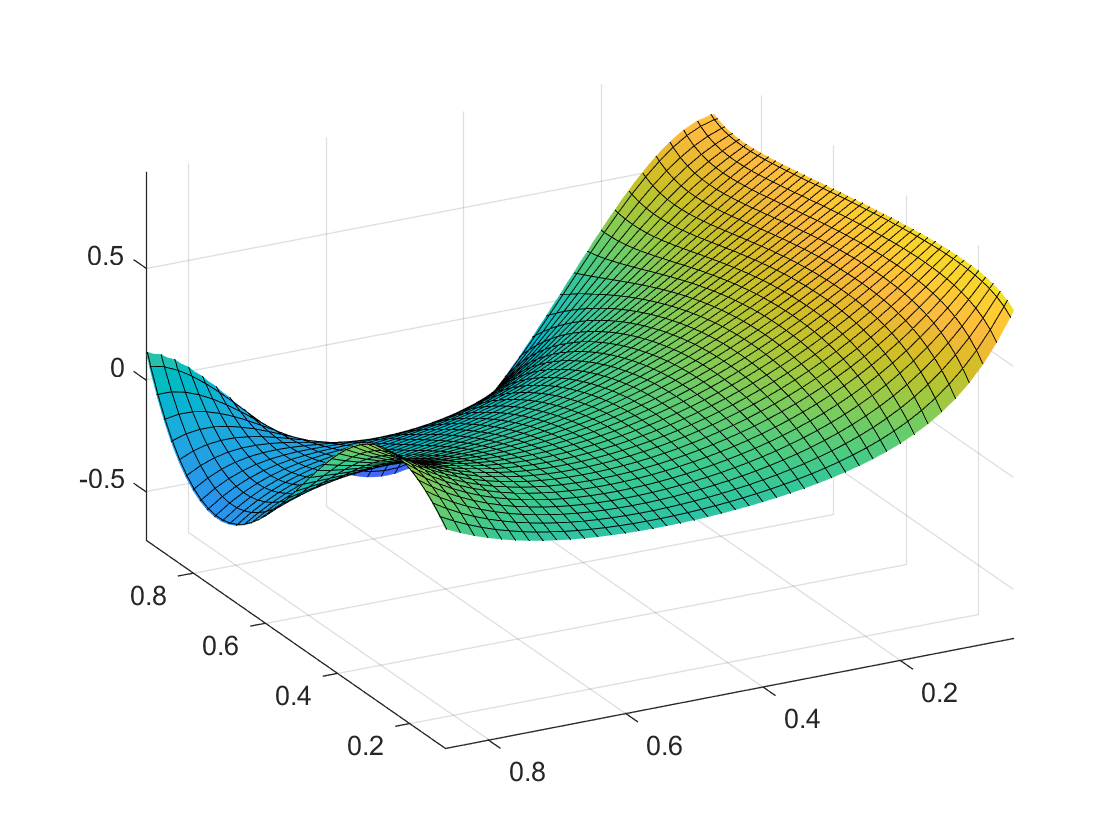

surf(x,y,Phi)
xlim([0.102 0.929])
ylim([0.035 0.862])
zlim([-0.72 0.93])
view([-117.78 32.40])

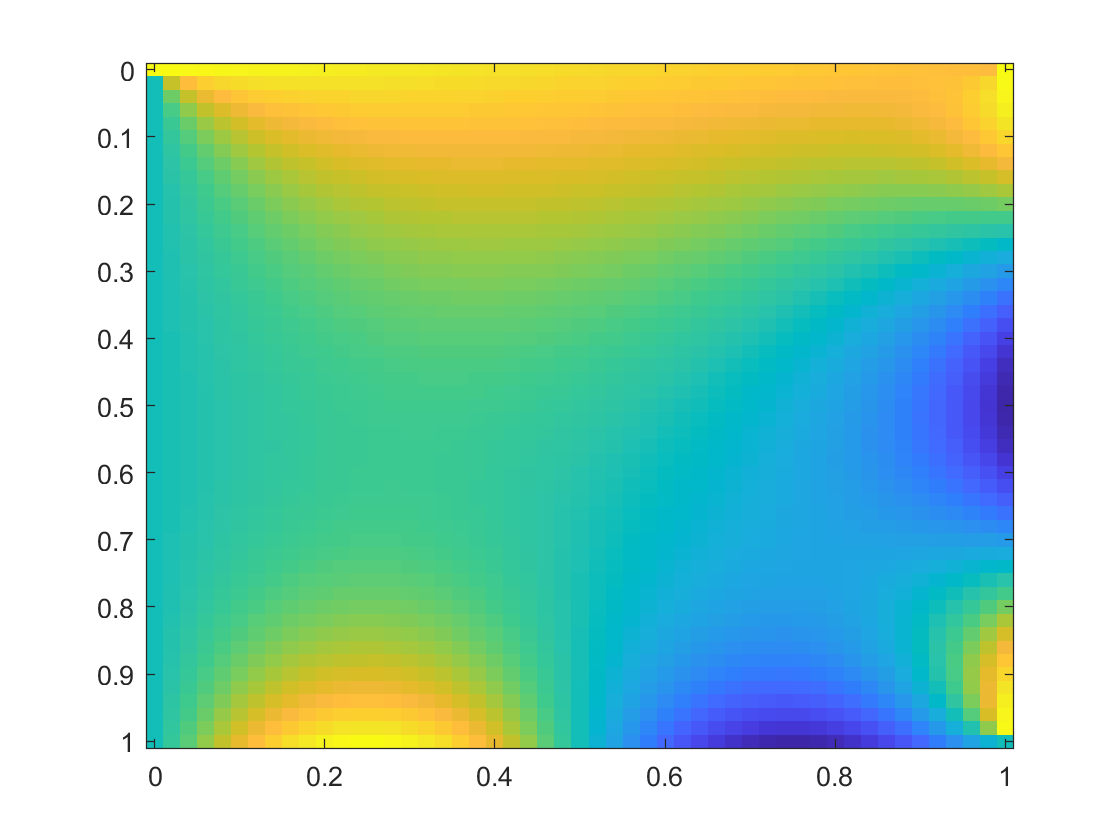

imagesc(x,y,Phi);

Phi

Phi =     1.0000    0.9933    0.9867    0.9800    0.9733    0.9667    0.9600    0.9533    0.9467    0.9400    0.9333    0.9267    0.9200    0.9133    0.9067    0.9000    0.8933    0.8867    0.8800    0.8733    0.8667    0.8600    0.8533    0.8467    0.8400    0.8333    0.8267    0.8200    0.8133    0.8067    0.8000    0.7933    0.7867    0.7800    0.7733    0.7667    0.7600    0.7533    0.7467    0.7400    0.7333    0.7267    0.7200    0.7133    0.7067    0.7000    0.6933    0.6867    0.6800    0.6733
         0    0.4930    0.6837    0.7697    0.8136    0.8380    0.8521    0.8602    0.8645    0.8663    0.8663    0.8650    0.8627    0.8597    0.8560    0.8519    0.8473    0.8425    0.8373    0.8319    0.8263    0.8205    0.8145    0.8084    0.8021    0.7958    0.7893    0.7828    0.7761    0.7694    0.7627    0.7559    0.7491    0.7423    0.7356    0.7289    0.7223    0.7159    0.7098    0.7039    0.6985    0.6938    0.6900    0.6874    0.6867    0.6889    0.6956    0.7107    0.7424   